Create some arbitrary basal rate data exactly aligned on 5 minutes. Using interpoalte the result should have no error.

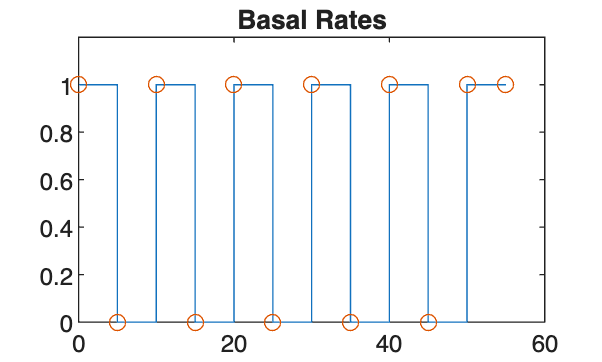

n=12;
minutes = (0:5:5*(n-1))';
dt = minutes/(24*60);
br = ones(n,1); br(2:2:end-1)=0;
stairs(minutes,br); ylim([0,1.2]); 
hold on
scatter(minutes,br)
hold off
title("Basal Rates")

Now, interpolate

[dti,U] = AIDIF.interpolateBasal( dt,br);
stem(dti*24*60,U)
U

U =     0.0833
         0
    0.0833
         0
    0.0833
         0
    0.0833
         0
    0.0833
         0
    0.0833
         0


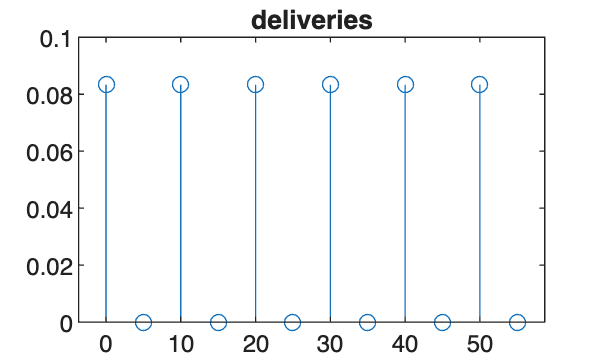

title("deliveries")

Compare 

disp(['Sum of U: ', num2str(sum(U)),', expected value: ', num2str(floor(n/2)*5/60)]);

Sum of U: 0.5, expected value: 0.5


assert(abs(sum(U) - floor(n/2)*5/60) < 1e-10)